Load equations and symbols from file

load symbols.mat
load CoreEquations.mat
load DesignParameters.mat

Calculate torque requirements for different movements

%Stage 1: Lifting against step from ground, calculate stall torque
Eqns=[
    %Load Core equations (sum of forces, moments, kinematics)
    Core_equations; DesignParameters
    %Load conditional equations for specified movement
    condition_2d; condition_tailOnGround; condition_wheel1locked; condition_wheel2NoContact; condition_angle_quadrants;
    %Set position of front wheel
    s51 == -rw; s52 == rw;
    %Set accellerations to zero to solve for stalling torque
    unwrap_y(a == 0)
    %Set the state of the device
    t13 == 0; t23 == 0;
    tv13 == 0; tv23 == 0;
    ];

sol1 = mysolver(Eqns);
sol1.T_z
%Draw positions
drawfigure(sol1);

%Stage 3: Pulling up step with tail on ground, calculate stall torque
Eqns=[
    %Load Core equations (sum of forces, moments, kinematics)
    Core_equations; DesignParameters
    %Load conditional equations for specified movement
    condition_2d; condition_tailOnGround; condition_rolling; condition_wheel2NoContact; condition_angle_quadrants;
    %Set position of front wheel
    s51 == step_width-rw-0.075; s52 == rw+step_height;
    %Set vertical accelleration of bottom wheel to zero to solve for lifting torque
    a62 == 0;
    %Set the state of the device
    s62 == rw; t23 == 0;
    tv13 == 0; tv23 == 0;
    ];

[sol2, unsolved] = mysolver(Eqns, 1);
sol2.T_z
drawfigure(sol2);

%Stage 3: Pulling up step with tail on ground, calculate stall torque
Eqns=[
    %Load Core equations (sum of forces, moments, kinematics)
    Core_equations; DesignParameters
    %Load conditional equations for specified movement
    condition_2d; condition_tailOnGround; condition_rolling; condition_wheel2NoContact; condition_angle_quadrants;
    %Set position of front wheel
    s51 == step_width-rw-0.075; s52 == rw+step_height;
    %Set vertical accelleration of bottom wheel to zero to solve for lifting torque
    a62 == 0;
    %Set the state of the device
    t13 == 0; t23 == 0;
    tv13 == 0; tv23 == 0;
    ];

sol3 = mysolver(Eqns);
sol3.T_z
drawfigure(sol3);

%Stage 1: Lifting against step from first step with tail on ground, calculate stall torque
Eqns=[
    %Load Core equations (sum of forces, moments, kinematics)
    Core_equations; DesignParameters
    %Load conditional equations for specified movement
    condition_2d; condition_tailOnGround; condition_wheel1locked; condition_wheel2NoContact; condition_angle_quadrants;
    %Set position of front wheel
    s51 == step_width-rw; s52 == rw+step_height;
    %Set accellerations to zero to solve for stalling torque
    unwrap_y(a == 0)
    %Set the state of the device
    pi/2 < t73; t73 < pi;
    t13 == 0; t23 == 0;
    tv13 == 0; tv23 == 0;
    ];

sol3 = mysolver(Eqns);
sol3.T_z
drawfigure(sol3);

%Stage 6: Pulling up step with tail on step, calculate stall torque
Eqns=[
    %Load Core equations (sum of forces, moments, kinematics)
    Core_equations; DesignParameters
    %Load conditional equations for specified movement
    condition_2d; condition_tailOnStep; condition_rolling; condition_wheel2NoContact; condition_angle_quadrants;
    %Set position of front wheel
    s51 == 2*step_width-rw-0.075; s52 == rw+2*step_height;
    %Set vertical accelleration of bottom wheel to zero to solve for lifting torque
    a62 == 0;
    %Set step that contacts tail
    N2==1;
    %Set the state of the device
    s62 == rw+step_height; t23 == 0;
    tv13 == 0; tv23 == 0;
    ];

sol4 = mysolver(Eqns);
sol4.T_z
drawfigure(sol4);

%Stage 6:Pulling up step with tail on step, calculate stall torque
Eqns=[
    %Load Core equations (sum of forces, moments, kinematics)
    Core_equations; DesignParameters
    %Load conditional equations for specified movement
    condition_2d; condition_tailOnStep; condition_rolling; condition_wheel2NoContact; condition_angle_quadrants;
    %Set position of front wheel
    s51 == 2*step_width-0.075; s52 == rw+2*step_height;
    %Set vertical accelleration of bottom wheel to zero to solve for lifting torque
    a62 == 0;
    %Set step that contacts tail
    N2==1;
    %Set the state of the device
    t13 == 0; t23 == 0;
    tv13 == 0; tv23 == 0;
    ];

sol5 = mysolver(Eqns);
sol5.T_z
drawfigure(sol5);

%Stage 4:Lifting against step from second step with tail on first step, calculate stall torque
Eqns=[
    %Load Core equations (sum of forces, moments, kinematics)
    Core_equations; DesignParameters
    %Load conditional equations for specified movement
    condition_2d; condition_tailOnStep; condition_wheel1locked; condition_wheel2NoContact; condition_angle_quadrants;
    %Set position of front wheel
    s51 == 2*step_width; s52 == rw+2*step_height;
    %Set accellerations to zero to solve for stalling torque
    unwrap_y(a == 0)
    %Set the state of the device
    %Set step that contacts tail
    N2==1;
    t13 == 0; t23 == 0;
    tv13 == 0; tv23 == 0;
    ];
sol6 = mysolver(Eqns);
sol6.T_z
drawfigure(sol6);

%Test stall torques across stage 1 movement
Eqns=[
    %Load Core equations (sum of forces, moments, kinematics)
    Core_equations; DesignParameters
    %Load conditional equations for specified movement
    condition_2d; condition_tailOnGround; condition_wheel1locked; condition_wheel2NoContact; condition_angle_quadrants;
    %Set position of front wheel
    s51 == 0; s52 == rw;
    %Set accellerations to zero to solve for stalling torque
    unwrap_y(a == 0)
    %Set the state of the device
    tv13 == 0; tv23 == 0;
    ];
[sol, unsolved] = mysolver(Eqns, 0)
solutions2 = []
for i = linspace(0, pi/2, 100)
    solutions1 = [solutions1; mysolver([unsolved; t13 == i; t23 == 0;], 1)];
end

for i = 1:length(solutions1)
    Trange(i) = solutions1(i).T_z;
    thetarange(i) =solutions1(i).t13*180/pi;
end

plot(thetarange, Trange)
xlim([0,90])
ylim([0, 1.2])
ylabel("Torque required [Nm]")
xlabel("LIM Angle [°]")

%Test stall torques across stage 3 movement
Eqns=[
    %Load Core equations (sum of forces, moments, kinematics)
    Core_equations; DesignParameters
    %Load conditional equations for specified movement
    condition_2d; condition_tailOnGround; condition_rolling; condition_wheel2NoContact; condition_angle_quadrants;
    %Set position of front wheel
    s51 == step_width-rw-0.075; s52 == rw+step_height;
    %Set vertical accelleration of bottom wheel to zero to solve for lifting torque
    a62 == 0;
    %Set the state of the device
    t23 == 0;
    tv13 == 0; tv23 == 0;
    ];
[sol, unsolved] = mysolver(Eqns, 0)
solutions3 = []
for i = linspace(-0.74188086214972967258453186960347, 0, 100)
    solutions3 = [solutions3; mysolver([unsolved; t13 == i; t23 == 0;], 1)];
    solutions3(end).T_z
end

for i = 1:length(solutions3)
    Trange(i) = solutions3(i).T_z;
    thetarange(i) =solutions3(i).t13*180/pi;
end

plot(thetarange, Trange)
xlim([-42.5,0])
ylim([0, 1.2])
ylabel("Torque required [Nm]")
xlabel("LIM Angle [°]")
hold off
Trange(end)/2

%Test stall torques across stage 4 movement
Eqns=[
    %Load Core equations (sum of forces, moments, kinematics)
    Core_equations; DesignParameters
    %Load conditional equations for specified movement
    condition_2d; condition_tailOnStep; condition_wheel1locked; condition_wheel2NoContact; condition_angle_quadrants;
    %Set position of front wheel
    s51 == 2*step_width; s52 == rw+2*step_height;
    %Set accellerations to zero to solve for stalling torque
    unwrap_y(a == 0)
    %Set the state of the device
    %Set step that contacts tail
    N2==1;
    t23 == 0;
    tv13 == 0; tv23 == 0;
    ];
[sol, unsolved] = mysolver(Eqns, 0)
solutions4 = []
for i = linspace(0, pi/2, 100)
    solutions4 = [solutions4; mysolver([unsolved; t13 == i; t23 == 0;], 1)];
    solutions4(end).T_z
end

for i = 1:length(solutions4)
    Trange(i) = solutions4(i).T_z;
    thetarange(i) =solutions4(i).t13*180/pi;
end

plot(thetarange, Trange)
xlim([0,90])
ylim([0, 1.4])
ylabel("Torque required [Nm]")
xlabel("LIM Angle [°]")


%Test stall torques across stage 6 movement
Eqns=[
    %Load Core equations (sum of forces, moments, kinematics)
    Core_equations; DesignParameters
    %Load conditional equations for specified movement
    condition_2d; condition_tailOnStep; condition_rolling; condition_wheel2NoContact; condition_angle_quadrants;
    %Set position of front wheel
    s51 == 2*step_width-0.075; s52 == rw+2*step_height;
    %Set vertical accelleration of bottom wheel to zero to solve for lifting torque
    a62 == 0;
    %Set step that contacts tail
    N2==1;
    %Set the state of the device
    t23 == 0;
    tv13 == 0; tv23 == 0;
    ];
[sol, unsolved] = mysolver(Eqns, 0)
solutions6 = []
for i = linspace(-0.74188086214972967258453186960347, 0, 100)
    solutions6 = [solutions6; mysolver([unsolved; t13 == i; t23 == 0;], 1)];
end

for i = 1:length(solutions6)
    Trange(i) = solutions6(i).T_z;
    thetarange(i) =solutions6(i).t13*180/pi;
end

plot(thetarange, Trange)
xlim([-42.5,0])
ylim([0, 1.4])
ylabel("Torque required [Nm]")
xlabel("LIM Angle [°]")
hold off
Trange(end)/2


%Test stall torques with varying gear ratios
%remove certain parameters
reducedParameters = setdiff(DesignParameters, assignment_gears)

$$reducedParameters = \left(\begin{array}{c} I_{3}=\frac{7895689082865203}{590295810358705651712}\\ m_{4}=m_{3}\\ m_{6}=m_{5}\\ I_{2}=\frac{5072990516485623}{73786976294838206464}\\ m_{5}=\frac{61510981196073}{562949953421312}\\ m_{1}=\frac{4781504232814939}{18014398509481984}\\ I_{5}=\frac{4513494634395559}{36893488147419103232}\\ m_{2}=\frac{126477183527763}{1125899906842624}\\ m_{7}=\frac{7763401967589507}{18014398509481984}\\ I_{1}=\frac{3543923826346153}{2305843009213693952}\\ g_{2}=\frac{981}{100}\\ \mathrm{ratio7Weight}=\frac{1}{4}\\ {\mathrm{step}}_{\mathrm{width}}=\frac{1}{5}\\ {\mathrm{step}}_{\mathrm{start1}}=0\\ {\mathrm{step}}_{\mathrm{start2}}=0\\ {\mathrm{step}}_{\mathrm{start3}}=0\\ {\mathrm{step}}_{\mathrm{height}}=\frac{3}{20}\\ m_{3}=\frac{2720084835359431}{72057594037927936}\\ I_{4}=I_{3}\\ I_{6}=I_{5}\\ I_{7}=\frac{7562429506300977}{2305843009213693952} \end{array}\right)$$

%add back certain parameters, and add relation for gear separations to be
%based on gear ratios
new_assignment_gears = [%r3 == 0.027612244897959183673469387755102;
    l5_ab == 0.041+0.07;
    rw == 0.075; l7_ab == 0.425; 
    N_idler == 33; N_sun == 50; C_friction7 == 0.2;];

reducedEquations = setdiff(Core_equations, eqns_radius)


new_eqns_radius = [r2==separation23*N_sun/(N_sun+N_idler)
    r3==separation35*N_idler/(N_planet+N_idler)
    r3==separation23*N_idler/(N_idler+N_sun)
    r4==r3
    r5==separation35*N_planet/(N_planet+N_idler)
    r6==r5];

Eqns=[
    %Load Core equations (sum of forces, moments, kinematics)
    reducedEquations; new_eqns_radius; reducedParameters; new_assignment_gears
    %Load conditional equations for specified movement
    condition_2d; condition_tailOnStep; condition_wheel1locked; condition_wheel2NoContact; condition_angle_quadrants;
    %Set position of front wheel
    s51 == 2*step_width; s52 == rw+2*step_height;
    %Set accellerations to zero to solve for stalling torque
    unwrap_y(a == 0)
    %Set the state of the device
    %Set step that contacts tail
    N2==1;
    t23 == 0;
    tv13 == 0; tv23 == 0;
    ];
[sol, unsolved] = mysolver(Eqns, 0)

sol = struct with fields:
       C_friction7: 0.2
         F_react53: 0.0
         F_react61: 0.0
         F_react62: 0.0
         F_react63: 0.0
         F_react73: 0.0
    F_reactPrime73: 0.0
                I1: 0.0015369319646590562551680125835674
                I2: 0.000068751841737150920660058550648586
                I3: 0.000013375817588925833023587828873868
                I4: 0.000013375817588925833023587828873868
                I5: 0.00012233851720283331582055097452866
                I6: 0.00012233851720283331582055097452866
                I7: 0.0032796810000000000025199842212942
         M_react61: 0.0
         M_react62: 0.0
         M_react63: 0.0
                N2: 1.0
           N_idler: 33.0
             N_sun: 50.0
               a11: 0.0
               a12: 0.0
               a13: 0.0
               a21: 0.0
               a22: 0.0
               a23: 0.0
               a31: 0.0
               a32: 0.0
               a33: 0.0
               a41: 0.0
             

T_max = [];
solutionset = [];
for j = 1:60
    Trange = []
    solutionsGR = []
    theta=linspace(0.4, 0.5, 10)
    [sol2, unsolved2]= mysolver([unsolved; N_planet == j], 0, sol);
    for i = 1:length(theta)
        solutionsGR = [solutionsGR; mysolver([unsolved2; t13 == theta(i)], 1, sol2)];
        Trange(i) = solutionsGR(i).T_z;
    end
    j
    [Tmax(j),idx] = max(Trange);
    solutionset = [solutionset; solutionsGR(idx)];
    T_max
    idx
end


Trange =

     []




solutionsGR =

     []



theta =     0.4000    0.4111    0.4222    0.4333    0.4444    0.4556    0.4667    0.4778    0.4889    0.5000


j = 1


T_max =

     []



idx = 3


Trange =

     []




solutionsGR =

     []



theta =     0.4000    0.4111    0.4222    0.4333    0.4444    0.4556    0.4667    0.4778    0.4889    0.5000


j = 2


T_max =

     []



idx = 3


Trange =

     []




solutionsGR =

     []



theta =     0.4000    0.4111    0.4222    0.4333    0.4444    0.4556    0.4667    0.4778    0.4889    0.5000


j = 3


T_max =

     []



idx = 4


Trange =

     []




solutionsGR =

     []



theta =     0.4000    0.4111    0.4222    0.4333    0.4444    0.4556    0.4667    0.4778    0.4889    0.5000


j = 4


T_max =

     []



idx = 4


Trange =

     []




solutionsGR =

     []



theta =     0.4000    0.4111    0.4222    0.4333    0.4444    0.4556    0.4667    0.4778    0.4889    0.5000


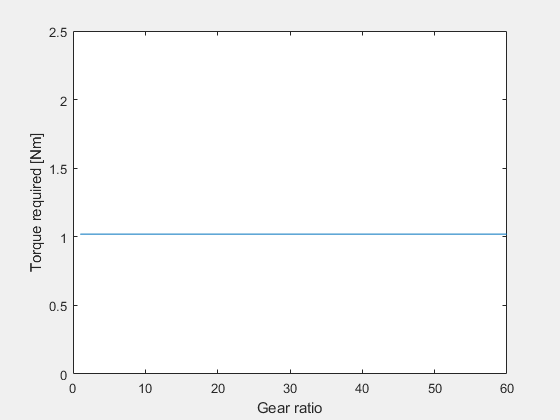

plot(1:60, Tmax)
% xlim([-42.5,0])
% ylim([0, 1.4])
ylabel("Torque required [Nm]")
xlabel("Gear ratio")
hold off

Create an animation by using the Runge Kutta method for discrete ODE solution

%Motor torque is not constant, create function to determine motor torque
%based on speed and voltage
motor_stallTorque = 6; % Nm
motor_NLSpeed = 0.6; %rad/s
syms speed stallTorque voltage 
eqns_motor = [
    speed == tv23;
    T_z == 2*motor_stallTorque*(voltage/12.0-speed/motor_NLSpeed)
    stallTorque == motor_stallTorque*(voltage/12.0)]

%Incomplete solution for movement1
Eqns=[
    %Load Core equations (sum of forces, moments, kinematics)
    Core_equations; DesignParameters
    %Load conditional equations for specified movement
    condition_2d; condition_tailOnGround; condition_wheel1locked; condition_wheel2NoContact; eqns_motor; condition_angle_quadrants;
    %Set position of front wheel
    s51 == 0; s52 == rw;
    %Set Motor voltage 
    stallTorque == 6;
    ];

[sol, unsolved] = mysolver(Eqns, 0);

Eqns=[unsolved;
    t13 == 0; t23 ==0 
    tv13 == 0; tv23 == 0;
    ]; 
[sol2, unsolved2] = mysolver(Eqns, 1, sol)


%Start calculations
framesol = []
frameeqs = unsolved
Step_Value = 0.005;
t_beg = 0;
t_end = 10;
t_intial=0;
u_intial=[sol2.t13,sol2.t23,sol2.tv13,sol2.tv23];
% Routine starts here
h=Step_Value;
t=t_beg:h:t_end;
u=zeros(4,length(t));
u(:,1)=u_intial;




for i=1:(length(t)-1)
    t0=t(i);
    up1=u(1,i); %t13
    up2=u(2,i); %t23
    up3=u(3,i); %tv13
    up4=u(4,i); %tv23
    framesol = [framesol; mysolver([unsolved; t13 == up1; t23 == up2; tv13 == up3; tv23 == up4;], 1)];
    k1 = [framesol(i).tv13; framesol(i).tv23; framesol(i).ta13; framesol(i).ta23];
    tempsol = mysolver([unsolved; t13 == up1+0.5*h*k1(1); t23 == up2+0.5*h*k1(2); tv13 == up3+0.5*h*k1(3); tv23 == up4+0.5*h*k1(4);], 1);
    k2 = [tempsol.tv13; tempsol.tv23; tempsol.ta13; tempsol.ta23];
    tempsol = mysolver([unsolved; t13 == up1+0.5*h*k2(1); t23 == up2+0.5*h*k2(2); tv13 == up3+0.5*h*k2(3); tv23 == up4+0.5*h*k2(4);], 1);
    k3 = [tempsol.tv13; tempsol.tv23; tempsol.ta13; tempsol.ta23];
    tempsol = mysolver([unsolved; t13 == up1+k3(1)*h; t23 == up2+k3(2)*h; tv13 == up3+k3(3)*h; tv23 == up4+k3(4)*h], 1);
    k4 = [tempsol.tv13; tempsol.tv23; tempsol.ta13; tempsol.ta23];
    u(:,i+1) = u(:,i) + (h/6)*(k1+2*k2+2*k3+k4);
    i
end

f = fieldnames(sol)
nframes = length(framesol)
for i = 1:length(f)
    for j = 1:nframes
        framesol(j).(f{i}) = sol.(f{i});
    end
end

F(length(framesol)) = struct('cdata',[],'colormap',[]);
for j=1:length(framesol)
    f=figure('visible','off');
    hold on;
    %wheels
    circle(framesol(j).s61, framesol(j).s62, framesol(j).rw);
    line([framesol(j).s61,framesol(j).s61+framesol(j).rw*cos(-framesol(j).t63+pi/4)],[framesol(j).s62,framesol(j).s62+framesol(j).rw*sin(-framesol(j).t63+pi/4)])
    
    circle(framesol(j).s51, framesol(j).s52, framesol(j).rw);
    line([framesol(j).s51,framesol(j).s51+framesol(j).rw*cos(-framesol(j).t53+pi/4)],[framesol(j).s52,framesol(j).s52+framesol(j).rw*sin(-framesol(j).t53+pi/4)])
    
    %frame
    line([framesol(j).s51,framesol(j).s61],[framesol(j).s52,framesol(j).s62])
    
    %Tail
    line([framesol(j).s11,framesol(j).s7End1],[framesol(j).s12,framesol(j).s7End2])
    
    axis equal;
    xlim([-0.6,1])
    %ylim([-0.1, 0.5])
    %step
    corner(:,1) = [framesol(j).step_start1-10; framesol(j).step_start2];
    for i= 1:5
        corner(:,2*i) =  [framesol(j).step_start1+framesol(j).step_width*(i-1); framesol(j).step_start2+framesol(j).step_height*(i-1)];
        corner(:,2*i+1) =  [framesol(j).step_start1+framesol(j).step_width*(i-1); framesol(j).step_start2+framesol(j).step_height*(i)];
    end
    line(corner(1,:), corner(2,:))
    hold off;
    F(j) = getframe(gcf);
end

fig = figure;



movie(fig, F, 1, 1/h);



f=figure('visible','on');
hold on;
%wheels
circle(sol.s61, sol.s62, sol.rw);
line([sol.s61,sol.s61+sol.rw*cos(-sol.t63+pi/4)],[sol.s62,sol.s62+sol.rw*sin(-sol.t63+pi/4)])

circle(sol.s51, sol.s52, sol.rw);
line([sol.s51,sol.s51+sol.rw*cos(-sol.t53+pi/4)],[sol.s52,sol.s52+sol.rw*sin(-sol.t53+pi/4)])

%frame
line([sol.s51,sol.s61],[sol.s52,sol.s62])

%Tail
line([sol.s11,sol.s7End1],[sol.s12,sol.s7End2])

axis equal;
xlim([-0.6,1])
%ylim([-0.1, 0.5])
%step
corner(:,1) = [sol.step_start1-10; sol.step_start2];
for i= 1:5
    corner(:,2*i) =  [sol.step_start1+sol.step_width*(i-1); sol.step_start2+sol.step_height*(i-1)];
    corner(:,2*i+1) =  [sol.step_start1+sol.step_width*(i-1); sol.step_start2+sol.step_height*(i)];
end
line(corner(1,:), corner(2,:))
% line([sol.step_start1-10, sol.step_start1], [sol.step_start2,sol.step_start2])
% line([sol.step_start1, sol.step_start1], [sol.step_start2, sol.step_start2+ sol.step_height])
% line([sol.step_start1, sol.step_start1+sol.step_width], [sol.step_height, sol.step_height])
hold off;



function f = drawfigure(sol)
    f=figure('visible','on');
    hold on;
    %wheels
    circle(sol.s61, sol.s62, sol.rw);
    line([sol.s61,sol.s61+sol.rw*cos(-sol.t63+pi/4)],[sol.s62,sol.s62+sol.rw*sin(-sol.t63+pi/4)])
    
    circle(sol.s51, sol.s52, sol.rw);
    line([sol.s51,sol.s51+sol.rw*cos(-sol.t53+pi/4)],[sol.s52,sol.s52+sol.rw*sin(-sol.t53+pi/4)])
    
    %frame
    line([sol.s51,sol.s61],[sol.s52,sol.s62])
    
    %Tail
    line([sol.s11,sol.s7End1],[sol.s12,sol.s7End2])
    
    axis equal;
    xlim([-0.6,1])
    %ylim([-0.1, 0.5])
    %step
    corner(:,1) = [sol.step_start1-10; sol.step_start2];
    for i= 1:5
        corner(:,2*i) =  [sol.step_start1+sol.step_width*(i-1); sol.step_start2+sol.step_height*(i-1)];
        corner(:,2*i+1) =  [sol.step_start1+sol.step_width*(i-1); sol.step_start2+sol.step_height*(i)];
    end
    line(corner(1,:), corner(2,:))
    hold off;
end

function h = circle(x,y,r)
th = 0:pi/50:2*pi;
xunit = r * cos(th) + x;
yunit = r * sin(th) + y;
h = plot(xunit, yunit);
end